## MODELO DE FILTRO PASA BAJAS PASIVO

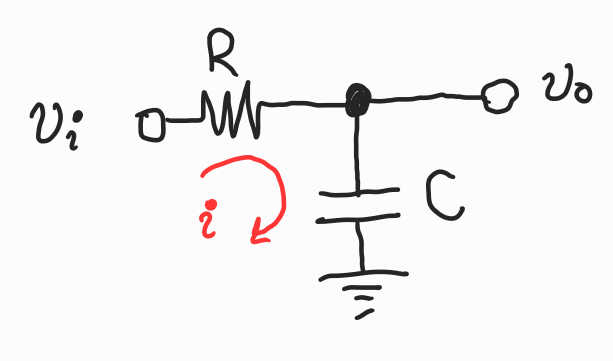

***Solución numérica***

$i_c(t)=C\frac{dv_c(t)}{dt}$        *Notación de Leibniz*

$i_c=C\dot{v_c}$        *Notación de Newton*

Sustitución de $i_c(t)$ en $v_c(t)$


$$v_s=RC\dot{v_c}+v_c$$



$$\dot{v_c}=\frac{v_s-v_c}{RC}$$


Discretizando la derivada


$$\frac{v_c^{(k+1)}-v_c^{(k)}}{T_s}=\frac{v_s^{(k)}-v_c^{(k)}}{RC}$$


Despejando para obtener el valor futuro $v_c^{(k+1)}$


$${v_c^{(k+1)}=\frac{T_s}{RC}\left(v_s^{(k)}-v_c^{(k)}\right)+v_c^{(k)}}$$


***Solución analítica (usando Laplace ***$\mathcal{L}$***)***


$$V_s(\mathcal{s})=V_R(\mathcal{s})+V_C(\mathcal{s})$$



$$V_R(\mathcal{s})=RI(\mathcal{s})$$



$$V_O(\mathcal{s})=V_C(\mathcal{s})=\frac{I(\mathcal{s})}{C\mathcal{s}}$$



$$G(\mathcal{s})=\frac{V_O(\mathcal{s})}{V_s(\mathcal{s})}=\frac{1}{RC\mathcal{s}+1}$$



$$V_s(\mathcal{s})=\frac{1}{\mathcal{s}}$$



$$V_O(\mathcal{s})=\frac{1}{RC\mathcal{s}+1}\cdot\frac{1}{\mathcal{s}}$$


Por fracciones parciales


$$V_O(\mathcal{s})=\frac{A}{RC\mathcal{s}+1}+\frac{B}{\mathcal{s}}$$



$$A=(RC\mathcal{s}+1)\cdot\frac{1}{RC\mathcal{s}+1}\cdot\frac{1}{\mathcal{s}}|_{\mathcal{s}=-\frac{1}{RC}}=-RC$$



$$B=(\mathcal{s})\cdot\frac{1}{RC\mathcal{s}+1}\cdot\frac{1}{\mathcal{s}}|_{\mathcal{s}=0}=1$$



$$V_O(\mathcal{s})=\frac{-RC}{RC\mathcal{s}+1}+\frac{1}{\mathcal{s}}$$



$$v_o(t)=1-e^{-\frac{t}{RC}}$$


Consideremos los siguientes datos como parámetros de funcionamiento del filtro.

$v_s=1V$,    $R=100\Omega$,    $C=10\mu F$,    $T_s=\frac{RC}{3}$

R = 100;
C = 10e-6;
Tao = R*C;
Ts = Tao/3;
t = 0: Ts: 6*Tao;

Calculando con las soluciones numérica y analítica

Vn = zeros(size(t));
for i = 2: length(t)
    Vn(i) = Ts/Tao*(1 - Vn(i - 1)) + Vn(i - 1);
end

Va = 1 - exp(-t/Tao);

Comparando soluciones

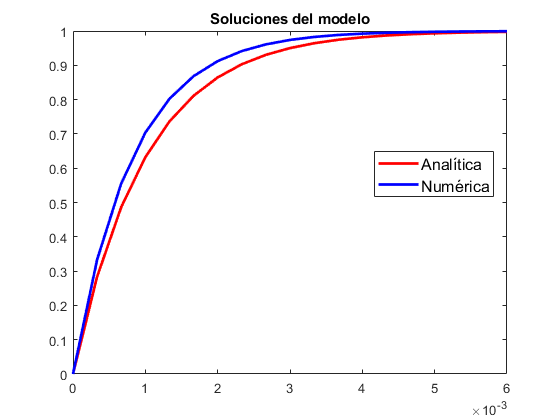

plot(t, Va, 'r', 'LineWidth', 2)
hold on
plot(t, Vn, 'b', 'LineWidth', 2)
hold off
legend({'Analítica', 'Numérica'}, 'FontSize', 12, 'Location',"best")
title('Soluciones del modelo')

Consideremos la solución analítica como el muestreo del sistema. Agregar un porcentaje de ruido $n(t)$y cuantificar$y(k)$ ayudará a simular la adquicisión de los datos con resolución de $b$-bits.

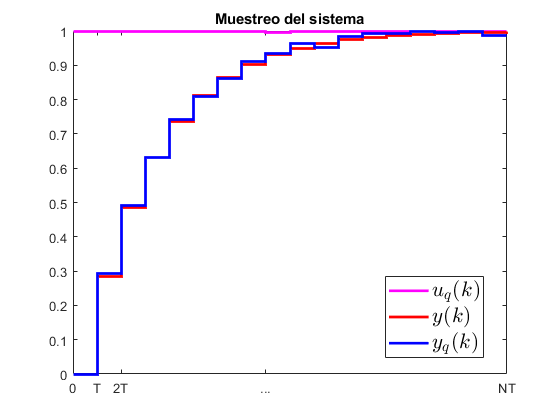

b = 8;
u = double(uencode(ones(size(t)) - 0.01*rand(size(t)) - 0.495, b, 0.5, 'unsigned'))'/(2^b-1);
y = double(uencode(Va - 0.025*rand(size(t)) - 0.4875, b, 0.5, 'unsigned'))'/(2^b-1)';
stairs(t, u, 'm', 'LineWidth', 2)
hold on
stairs(t, Va, 'r', 'LineWidth', 2)
stairs(t, y, 'b', 'LineWidth', 2)
hold off
xticks([t(1:3) t(floor(end/2)) t(end)])
xticklabels({'0' 'T' '2T' '...' 'NT'})
title('Muestreo del sistema')
legend({'$u_q(k)$' '$y(k)$' '$y_q(k)$'},'Interpreter', 'latex', "FontSize", 16, 'Location',"best")

Proponemos un orden $n=1$ para estimar una función de transferencia que describa al sistema muestreado a partir de la matriz $\Phi$.

n = 1;
Phi = GeneratePhi(u, y, n)

Phi =          0    1.0000
    0.2941    1.0000
    0.4902    1.0000
    0.6314    1.0000
    0.7412    1.0000
    0.8078    1.0000
    0.8627    1.0000
    0.9098    1.0000
    0.9333    0.9961
    0.9647    1.0000


Se compone la función de transferencia discreta a partir de la matriz obtenida

zTF = DiscreteModel(Phi, y, Ts)

zTF =
 
    0.2879
  ----------
  z - 0.7117
 
Sample time: 0.00033333 seconds
Discrete-time transfer function.



Conversión a función de transferencia continua

cTF = d2c(zTF, 'zoh')

cTF =
 
    1019
  --------
  s + 1020
 
Continuous-time transfer function.



Función de transferencia modelada

model = tf(1/Tao, [1 1/Tao])

model =
 
    1000
  --------
  s + 1000
 
Continuous-time transfer function.



Comparación de los diferentes modelos involucrados

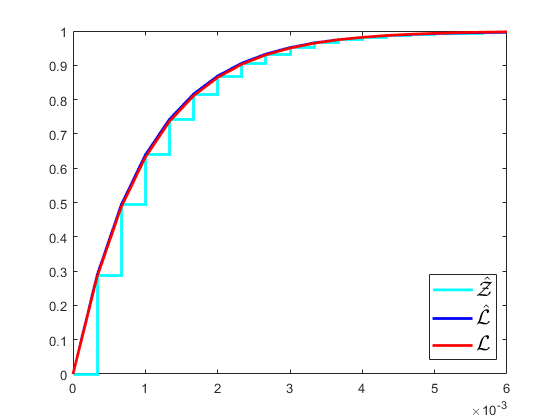

ze = step(zTF, t);
le = step(cTF, t);
lm = step(model, t);
stairs(t, ze, 'c', 'LineWidth', 2)
hold on
plot(t, le, 'b', 'LineWidth', 2)
plot(t, lm, 'r', 'LineWidth', 2)
hold off
legend({'$\hat{\mathcal{Z}}$', '$\hat{\mathcal{L}}$', '$\mathcal{L}$'},'Interpreter', 'latex', "FontSize", 16, 'Location', "best")

Ejemplo de las guías proporcionadas

ue = [0.1 0.2 0.6 0.7 0.4 0.45 0.35 0.9]';
ye = [10.1 11.2 15.3 16.5 14.5 14.8 14 17.5]';
Te = 1;
Phi = GeneratePhi(ue, ye, 2)

Phi =    11.2000   10.1000    0.2000    0.1000
   15.3000   11.2000    0.6000    0.2000
   16.5000   15.3000    0.7000    0.6000
   14.5000   16.5000    0.4000    0.7000
   14.8000   14.5000    0.4500    0.4000
   14.0000   14.8000    0.3500    0.4500


discrete = DiscreteModel(Phi, ye, Te)

discrete =
 
    -32.75 z + 11.93
  ---------------------
  z^2 - 3.656 z + 1.986
 
Sample time: 1 seconds
Discrete-time transfer function.



continuous = d2c(discrete,'tustin')

continuous =
 
  6.726 s^2 - 7.185 s - 12.54
  ---------------------------
     s^2 - 0.594 s - 0.403
 
Continuous-time transfer function.



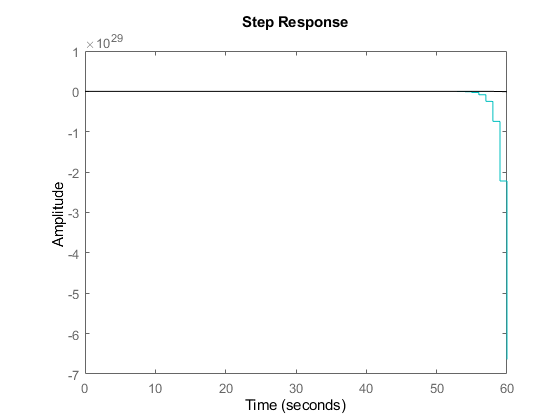

step(discrete, 'c')
hold on
step(continuous, 'k')
hold off

Función para generar $\Phi$

function [Phi] = GeneratePhi(u, y, order)
    NSamples = length(u);
    Phi = zeros(NSamples - order, 2*order);
    for r = 1: NSamples - order
        f = zeros(1, 2*order);
        for c = 1: order
            f(c) = y(r + order - c);
            f(order + c) = u(r + order - c);
        end
        Phi(r, :) = f;
    end
end

Función para generar la función de transferencia discreta $\mathcal{Z}$

function [zTF] = DiscreteModel(Phi, y, Ts)
    n = size(Phi, 2)/2;
    Theta = (Phi'*Phi)\Phi'*y(n + 1: end);
    zTF = tf(Theta(n + 1: end)', [1 -Theta(1:n)'], Ts);
end